**LHC**

For the LHC data, we are going to have to fake a background. Make a Poisson background with mean 100. 

background_dist = makedist('Poisson', "lambda", 100);

**Problem 1**

The first problem is to look at your background distribution and determine where the 5*σ*

 sensitivity threshold is. [Hint, you've done this several times now, look back at the first few labs.]

We report the five sigma probability as the probability of being further to the right than 5 sigma from the mean of a normal distribution. To find the 5 sigma threshold in our poisson background, we go to the point where the cumulative probability to the left of that point is equal to the cumulative probability to the left of +5 standard deviations from the mean in a normal distribution:

five_sigma_prob = 1 - normcdf(5)

five_sigma_prob =      2.866515719235352e-07


five_sigma_val = icdf(background_dist, 1-five_sigma_prob)

five_sigma_val =    154


**Problem 2**

Now inject a signal of known strength. You will want to make your signal moderately strong, say somewhere in the 8-30*σ *range. Inject this signal into your background data many times.

First, we generate 100k backgroud values. Then we generate signal value and add it to the background values.

background_values = random(background_dist, 100000, 1);

signal_sigma_value = 8;
signal_value = icdf(background_dist, normcdf(signal_sigma_value));
signal_with_background = background_values + signal_value;

a) Histogram how bright the observed signal appears to be, and discuss it's shape. Say in words what this histogram is telling you.

Unsurprisingly, the shape of the distribution of measured signal is the same as a the background, only shifted up by the signal value. This is unsurprising, given how this data set was constructed. Of note is that this does appear roughly normal in shape. Given that we have a Poisson distribution with a large size parameter, this is unsurprising. It is important to remember that it is still a discrete pdf though, an all the values should be integer differences from the injected signal value. 

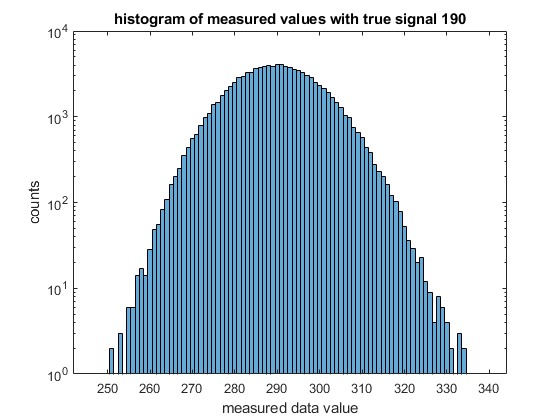


buffer = 3.5;
first_bin_edge = min(signal_with_background) - buffer;
last_bin_edge = max(signal_with_background) + buffer;
bin_edges = first_bin_edge:1:last_bin_edge;

figure
histogram(signal_with_background, 'BinEdges', bin_edges)
title(['histogram of measured values with true signal ' num2str(signal_value)])
xlabel('measured data value')
ylabel('counts')
set(gca, 'YScale', 'log')

b) Is your observed signal biased? (e.g. is the observed value  equally likely to be stronger or weaker than the true injected signal?)  Is it symmetric?

The observed signal is biased! Because our background is positive semi-definite, we expect that the measured signal will always be at least as large as the true signal. In more specifics, because the size parameter of our Poisson background is large, we expect almost all of the background to be significantly larger than zero (in this case we say significant as the majority of the background signal is on the same order as the signal value). The observed signal is fairly symmetric around the sum of the mean of the background and the injected signal. As mentioned earlier, the pdf for a Poisson with a large mean value is similar in shape to a Gaussian of the same mean and variance. We will use this fact to help motivate how to inject signals of 30*σ *in the next problem.

**Problem 3**

Now make a suite of injected signals. You will want to have a range  of injected signal strengths, starting at zero and extending well above 5*σ *(30*σ *or more). You will want to follow the work you did for Homework 5 very closely.

a) Clearly state what you are simulating, and make a 2D histogram of injected signal vs. observed data

I am injecting a range of signal values. Starting with a signal value of 0 and stepping by 10's up to 400 (roughly 30*σ *above the mean) , at each signal value I will simulate 100k background points to generate a distribution of measured values at each true signal value. I will then generate a 2D histogram of injected signval vs. observed data.

signal_values = 0:10:400;
number_signals = length(signal_values);
points_per_signal = 100000;

all_backgrounds = random(background_dist, points_per_signal, number_signals);
measured_values = zeros(points_per_signal, number_signals);

for i = 1:number_signals
    measured_values(:, i)= signal_values(i) + all_backgrounds(:, i);
end

b) For the same injected signal power as in problem 2, show that you get the same answer.

c) Now reverse the problem, select an observed data value (pick something quite a bit stronger than 5*σ*) and create a 1D histogram of the true signal probability given the observed data. Describe the meaning of this histogram.

d) For your observed signal, what is the 1*σ* uncertainty on the true signal strength?

e) Discuss the answer to part d in some depth. Is it symmetric? Is it biased? Does this make sense?